# Labb 2 - Spatial filtering

### 1) Testing different box filters

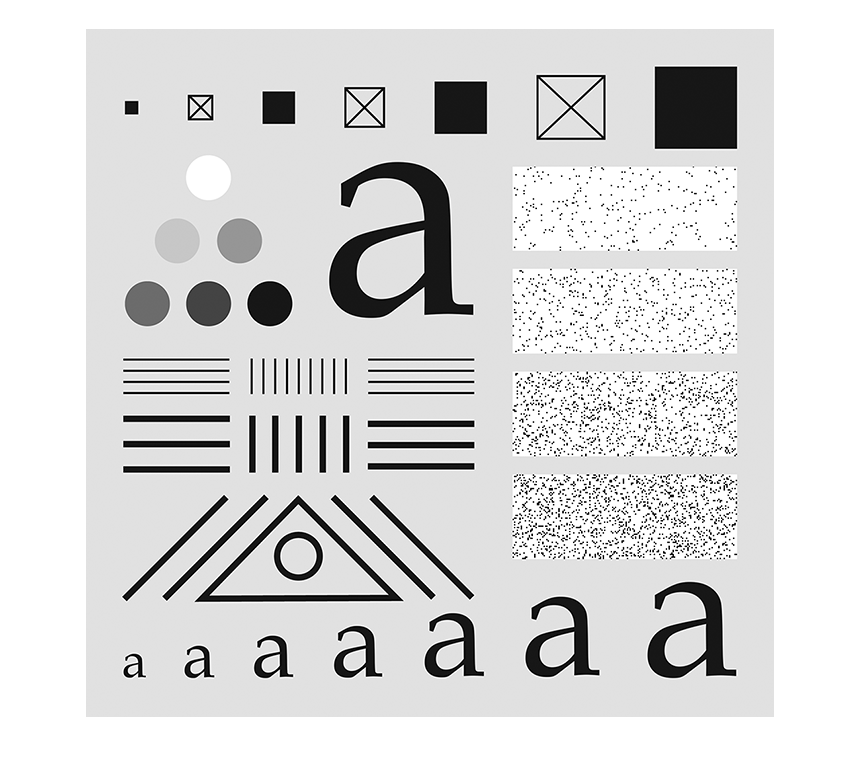

bild = imread("TestPattern.tif");
original = im2double(bild);
imshow(double)

Problem 1

box1 = ones(9)/(9)^2;
Image1 = imfilter(original,box1)

Image1 =     0.2720    0.3264    0.3808    0.4352    0.4897    0.4895    0.4895    0.4896    0.4896    0.4895    0.4895    0.4896    0.4896    0.4895    0.4897    0.4897    0.4897    0.4897    0.4897    0.4898    0.4898    0.4897    0.4897    0.4897    0.4897    0.4897    0.4898    0.4898    0.4899    0.4899    0.4899    0.4899    0.4899    0.4899    0.4899    0.4898    0.4898    0.4897    0.4897    0.4898    0.4898    0.4899    0.4899    0.4899    0.4899    0.4899    0.4900    0.4899    0.4898    0.4898
    0.3264    0.3917    0.4570    0.5222    0.5876    0.5875    0.5875    0.5876    0.5876    0.5875    0.5875    0.5876    0.5876    0.5875    0.5877    0.5877    0.5876    0.5877    0.5877    0.5877    0.5877    0.5876    0.5877    0.5876    0.5876    0.5876    0.5877    0.5877    0.5878    0.5878    0.5878    0.5878    0.5878    0.5878    0.5878    0.5877    0.5878    0.5877    0.5877    0.5878    0.5878    0.5879    0.5879    0.5879    0.5879    0.5879    0.5879    0.5879    0.5878

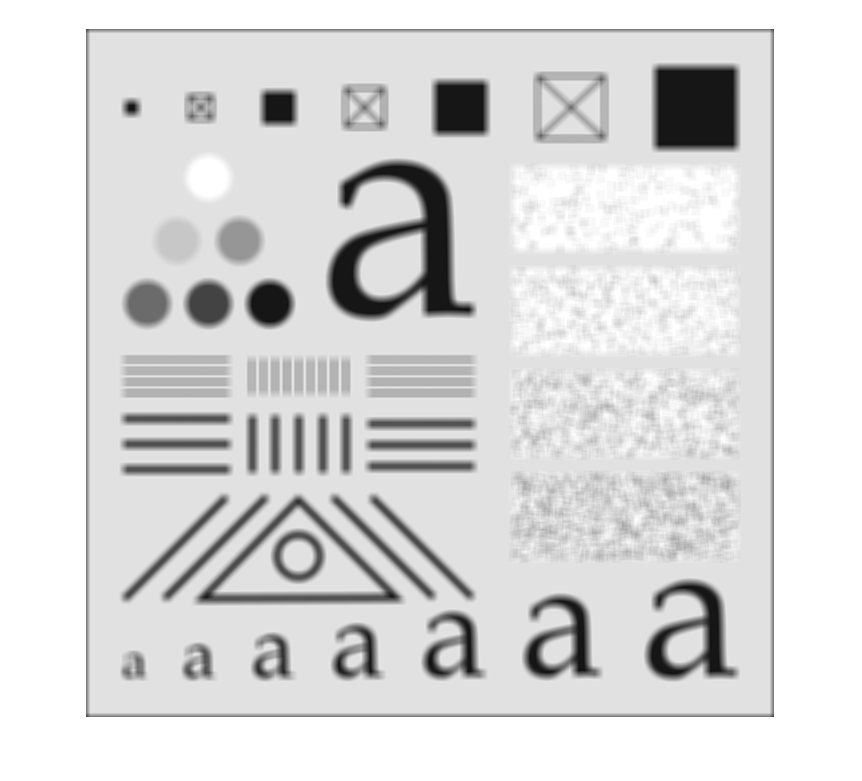

imshow(Image1)

Problem 2

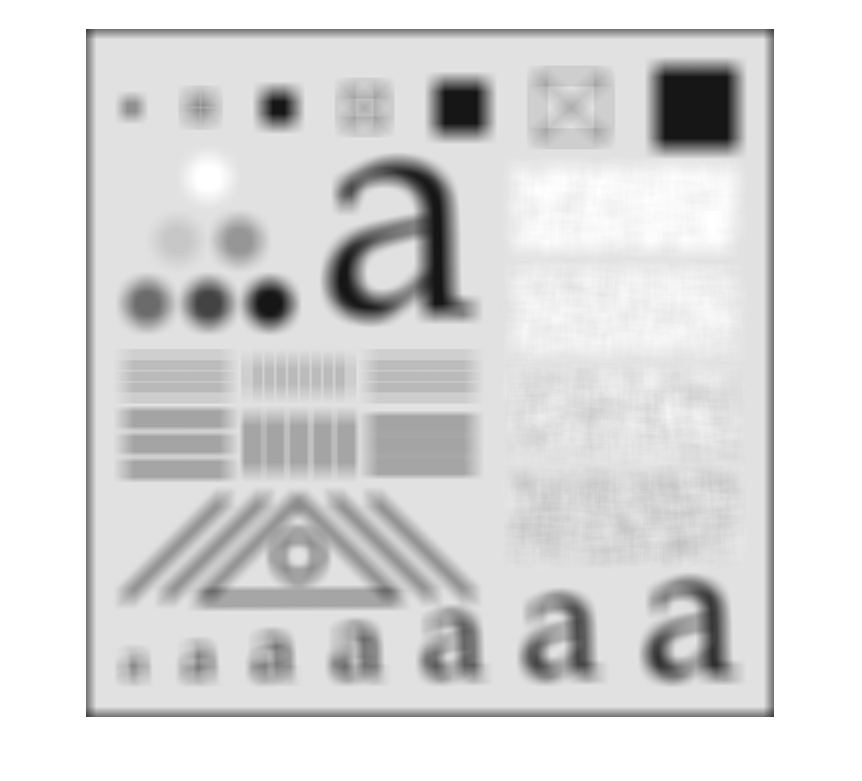

box2 = ones(21)/(21)^2;
Image2 = imfilter(original,box2);
imshow(Image2)

Problem 5

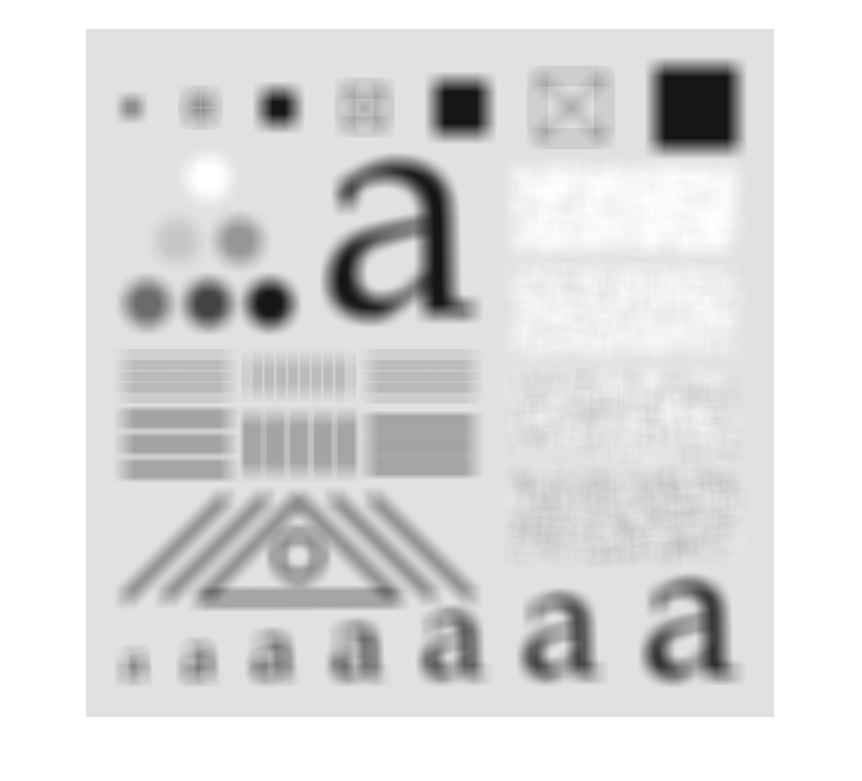

image3 = imfilter(original, box2, "replicate");
imshow(image3)

Problem 6

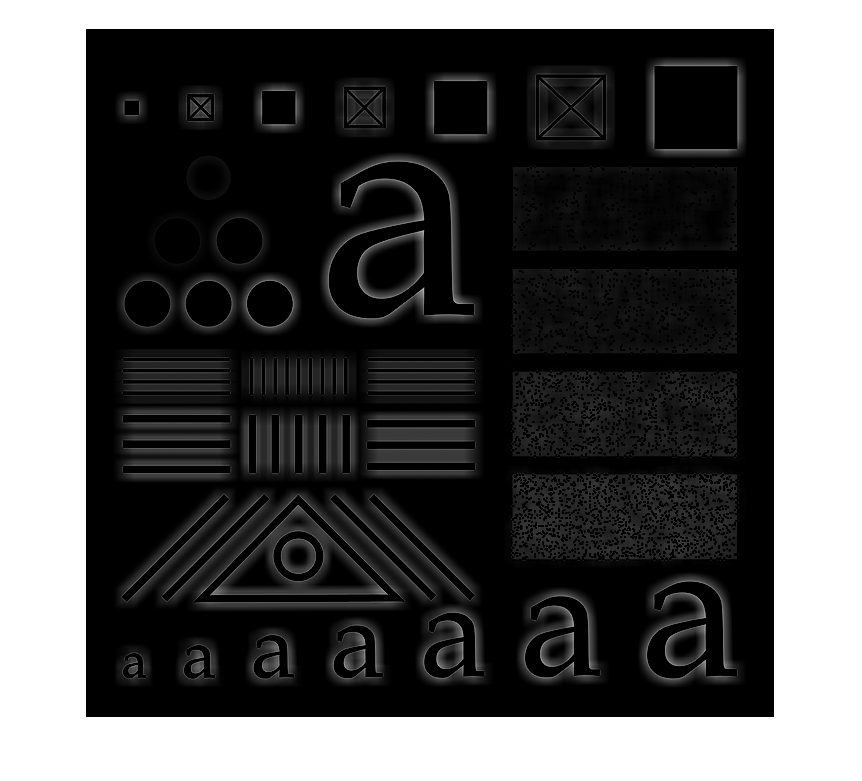

%föreläsning s.66
d = zeros(21);
d(11,11) = 1; %discrete impulse, mitten är 1

highpass = d - box2;
image4 = imfilter(original,highpass,"replicate");
imshow(image4)

% mean2(image4)


Problem 8

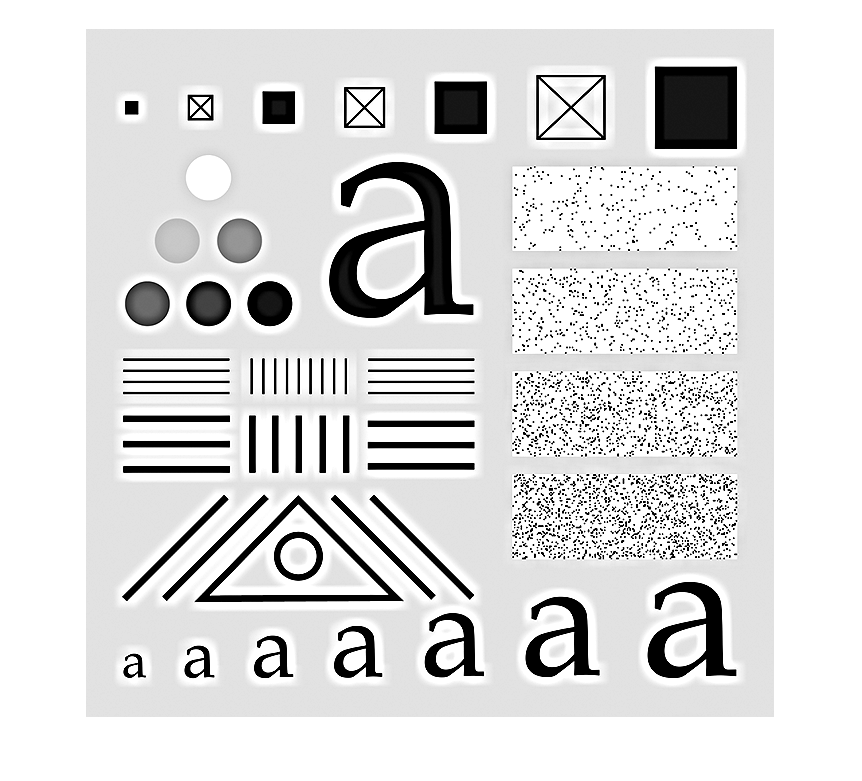

%unsharp masking
image5 = original + image4;
imshow(image5)

### 2) Testing sobel filters and gradient

Problem 9

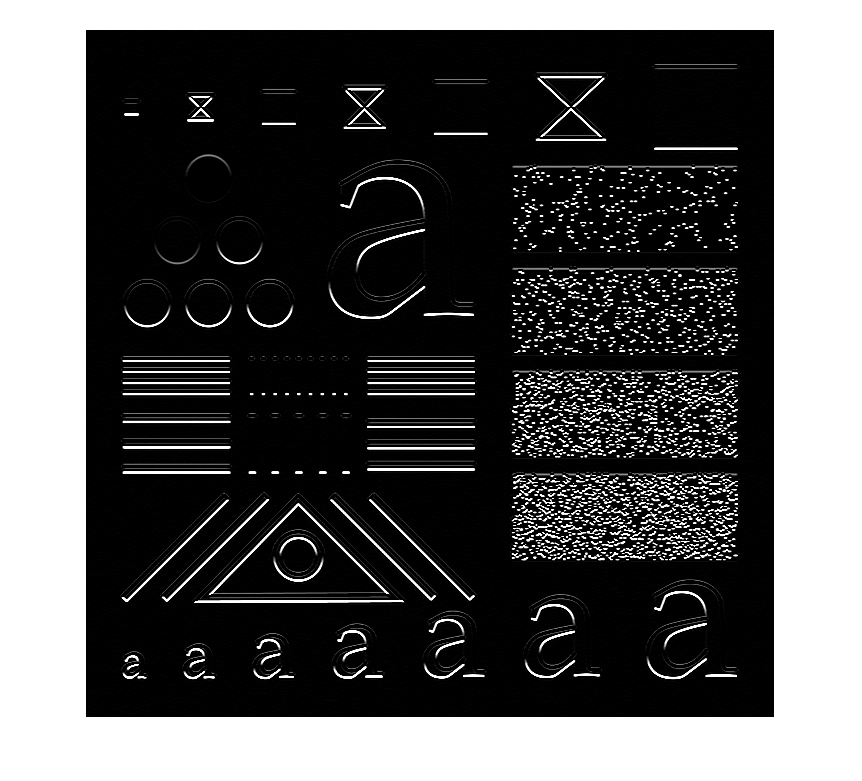

sobX = [-1 -2 -1; 0 0 0; 1 2 1];
sobY = [-1 0 1; -2 0 2; -1 0 1];

image6 = imfilter(original, sobX); %gx
image7 = imfilter(original, sobY); %gy

imshow(image6) 

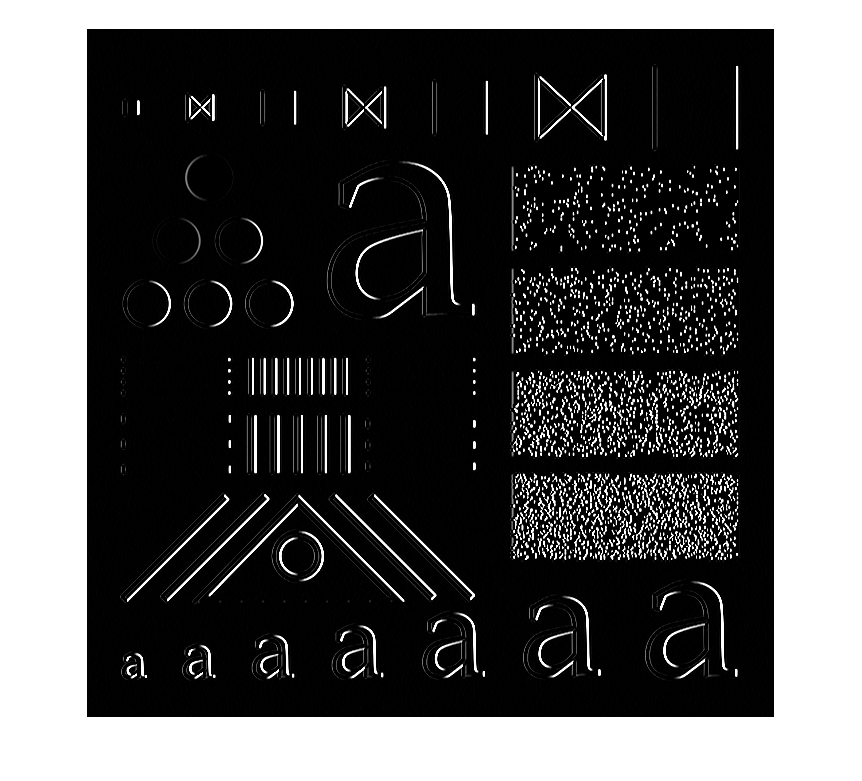

imshow(image7)

Problem 10

input = image6.^2 + image7.^2;
image8 = sqrt(input)

gradient =     3.7380    3.5216    3.5216    3.5216    3.5255    3.5294    3.5294    3.5294    3.5255    3.5216    3.5255    3.5294    3.5294    3.5294    3.5294    3.5294    3.5294    3.5294    3.5294    3.5294    3.5294    3.5294    3.5294    3.5294    3.5255    3.5216    3.5255    3.5294    3.5294    3.5294    3.5255    3.5216    3.5255    3.5294    3.5294    3.5294    3.5294    3.5294    3.5294    3.5294    3.5255    3.5216    3.5255    3.5255    3.5216    3.5255    3.5294    3.5294    3.5294    3.5294
    3.5216    0.0055    0.0055    0.0055    0.0078    0.0055    0.0055    0.0055    0.0124    0.0124    0.0111    0.0078    0.0124    0.0055         0    0.0055    0.0055    0.0055         0    0.0124    0.0124    0.0055    0.0055    0.0111    0.0111    0.0055    0.0124         0    0.0055    0.0055    0.0055         0    0.0078         0    0.0055    0.0078    0.0055         0    0.0055    0.0078    0.0078    0.0078    0.0124    0.0078         0    0.0078         0         0        

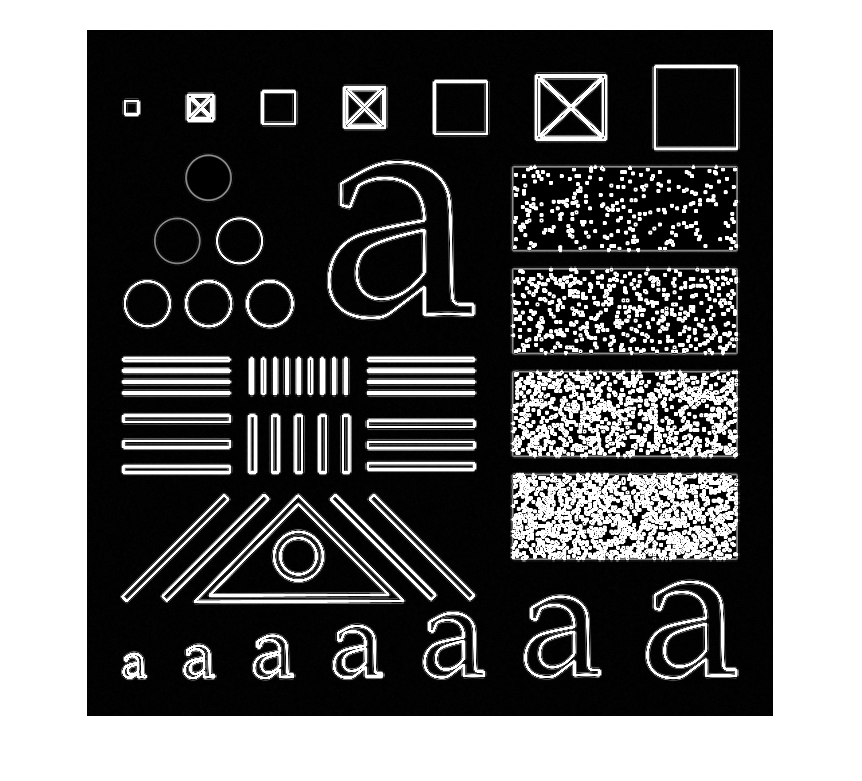

imshow(image8)

# Task 2 - MATLAB code for spatial filtering

% a = imread("testPattern.tif");
% b = imread("zoneplate.tif");
% org = im2double(b)
% lp1 = ones(9)/(9)^2;
% lp2 = ones(21)/(21)^2;
% [olp, ohp, obr, obp, oum, ohb]=myfilter(org, lp1, lp2);
% 
% imshow(olp)
% imshow(ohp)
% imshow(obr)
% imshow(obp)
% imshow(oum)
% imshow(ohp)

# Task 3 